# Image Reconstruct

In this script we try to use Morphological reconstruction to reconstruct the image with a marker on the arm. This doesn't really help

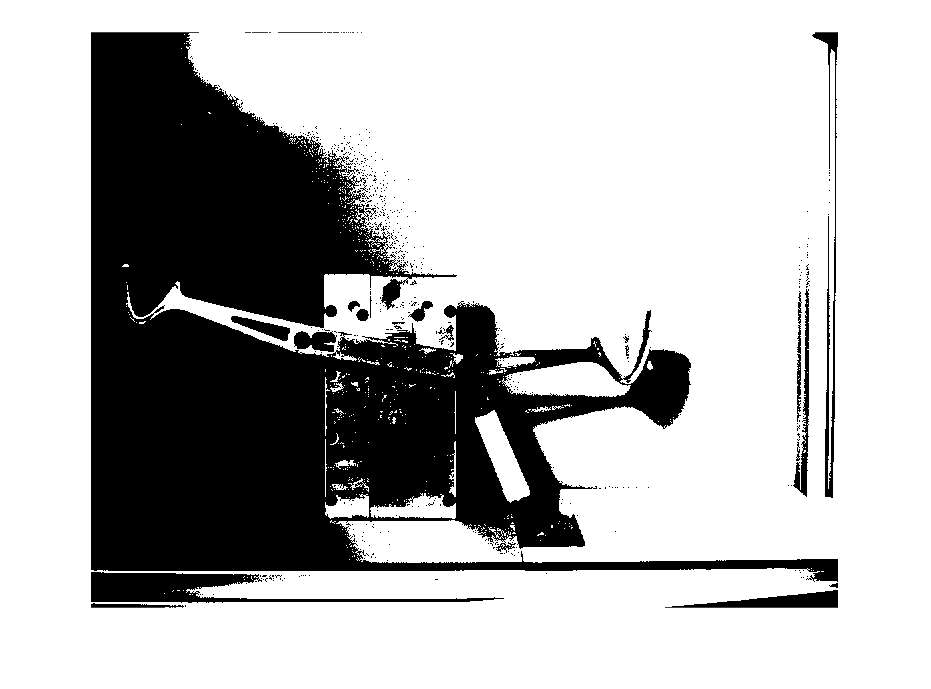

frame = video_data(1,:,:);
frame = squeeze(frame);

test = imbinarize(frame);
figure, imshow(test)

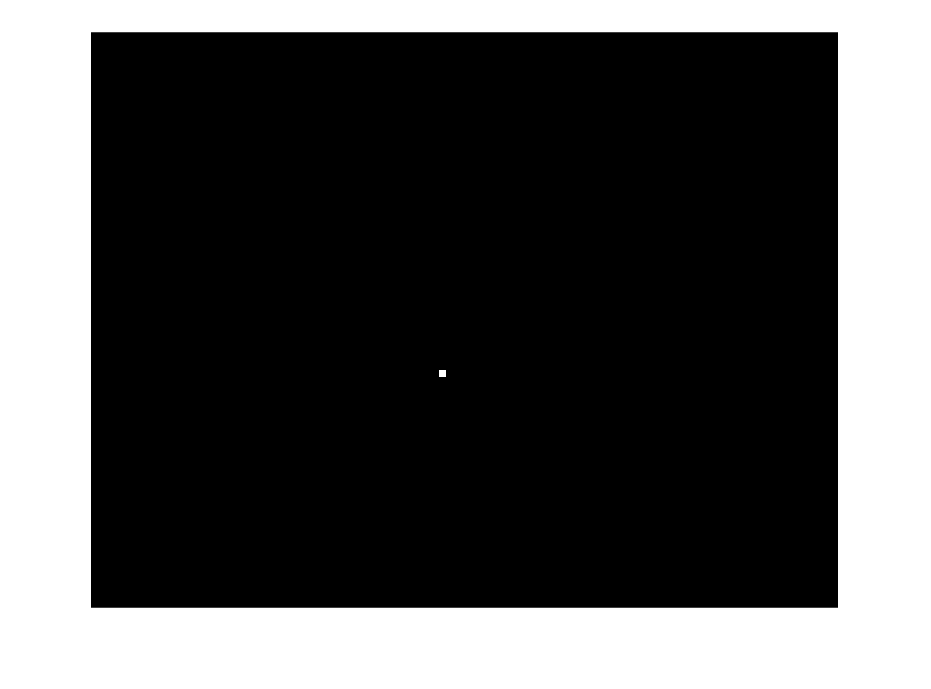


mask = frame;

row = 1024;
col = 1056;
r = 10;

marker = zeros(size(mask));
% Define the square region
row_range = max(1, row-r):min(size(marker, 1), row+r); % Ensure within bounds
col_range = max(1, col-r):min(size(marker, 2), col+r); % Ensure within bounds
% Set the square region to true
marker(row_range, col_range) = 255;
marker = uint8(marker);
figure, imshow(marker);

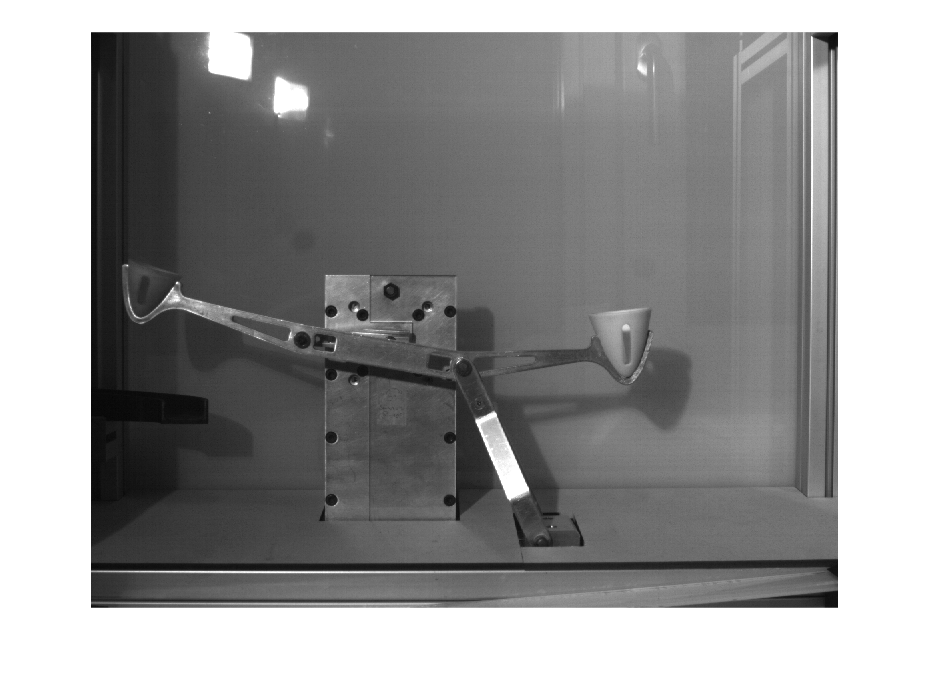

figure, imshow(mask);

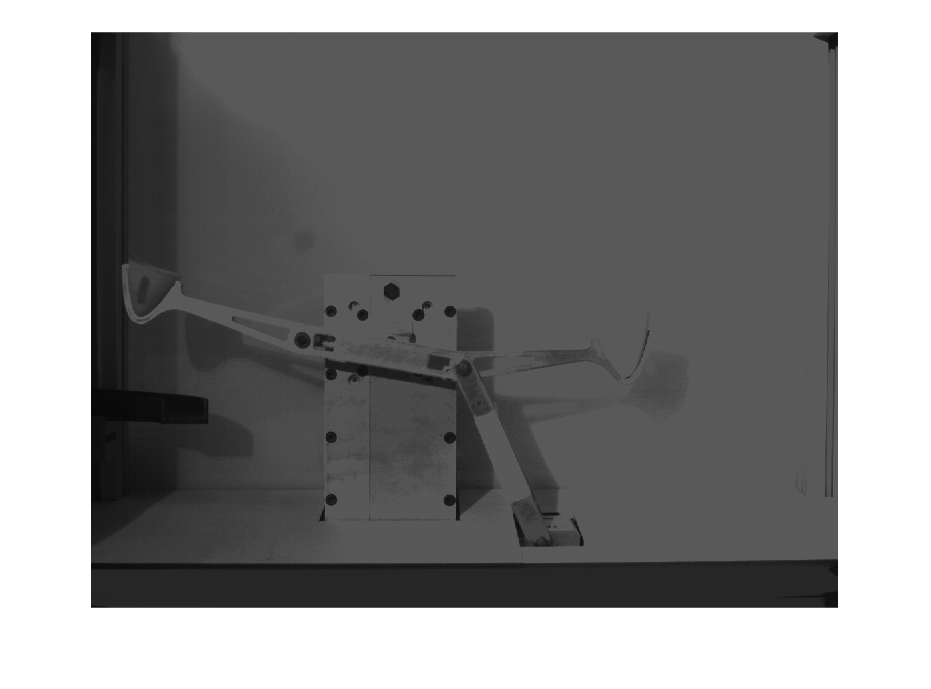


im = imreconstruct(marker,mask, 8); % Default = 8 (other option is 4)
figure, imshow(im)

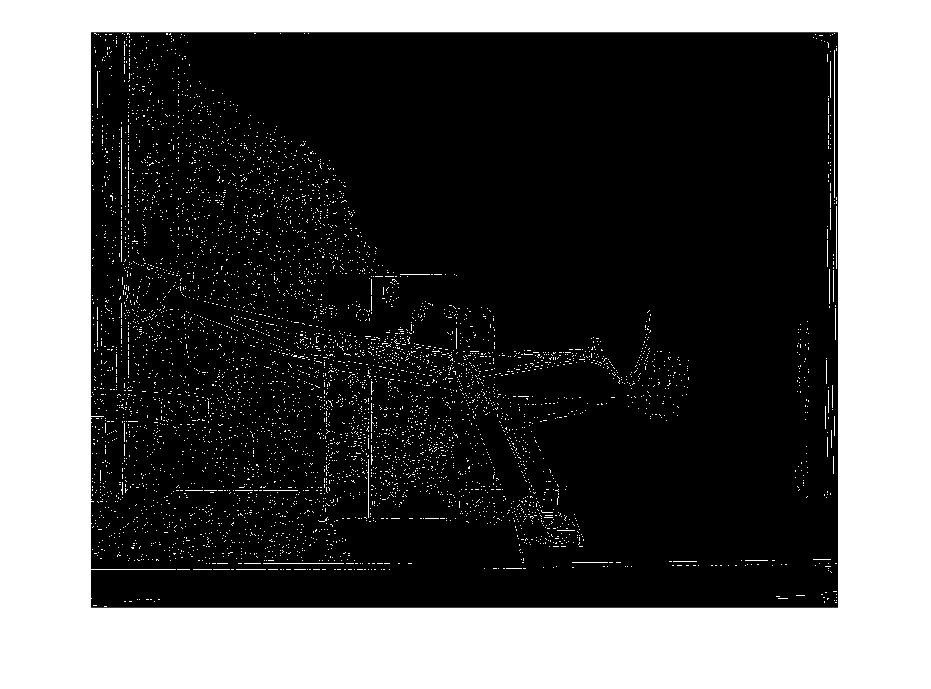

% Edge detection is worse
frameBlur = imgaussfilt(im, 2);
edgeIm = edge(frameBlur, "zerocross");
figure, imshow(edgeIm);

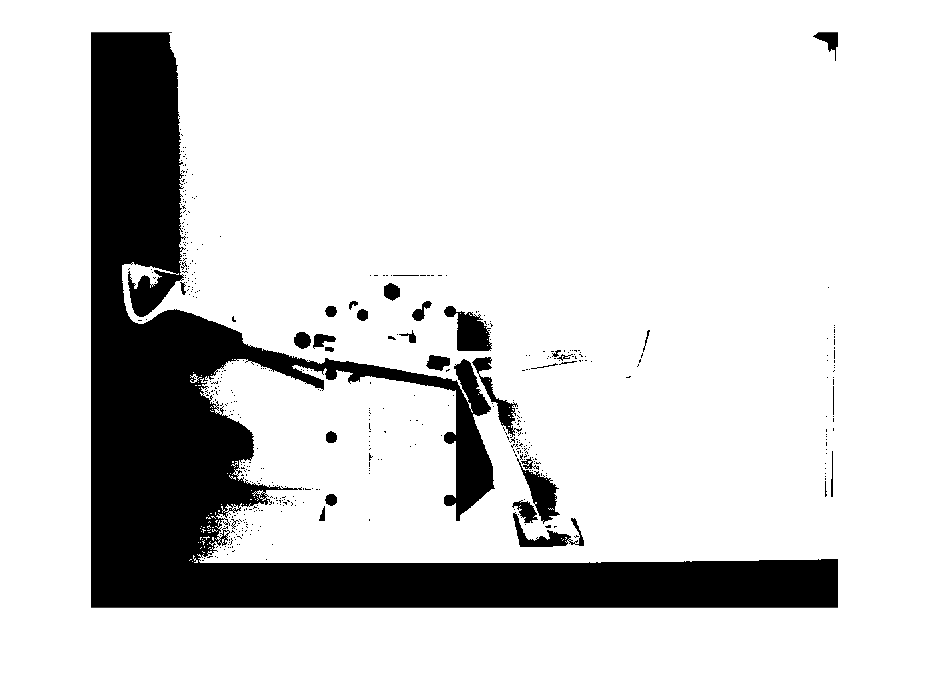


% Binary image is worse

binIm = imbinarize(im);
figure, imshow(binIm);